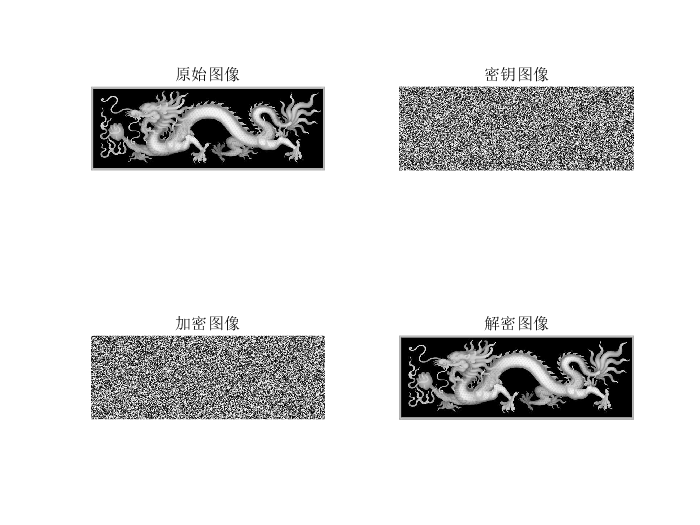

clc;clear;
a=imread('grey.jpeg');
subplot(2,2,1);
imshow(a);
title('原始图像');
%生成密钥图像
keys=grey(0.69,size(a,1),size(a,2));
subplot(2,2,2);
imshow(keys,[]);
title('密钥图像');
%生成加密图像
a_mi=bitxor(keys,a);
subplot(2,2,3);
imshow(a_mi,[]);
title('加密图像');
%解密图像
a_jie=bitxor(a_mi,keys);
subplot(2,2,4);
imshow(a_jie);
title('解密图像')